# Live SFM analysis

## Show trajectory

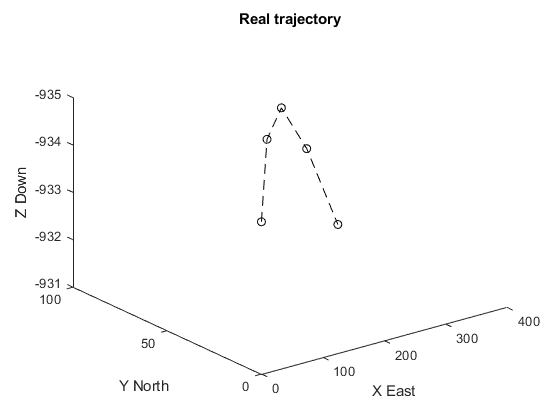

figure;plot3(cam_x,cam_y,cam_z,'k--o');
title("Real trajectory");
xlabel(" X East");
ylabel("Y North");
zlabel("Z Down")
set(gca, 'ZDir','reverse');

## Show cameras

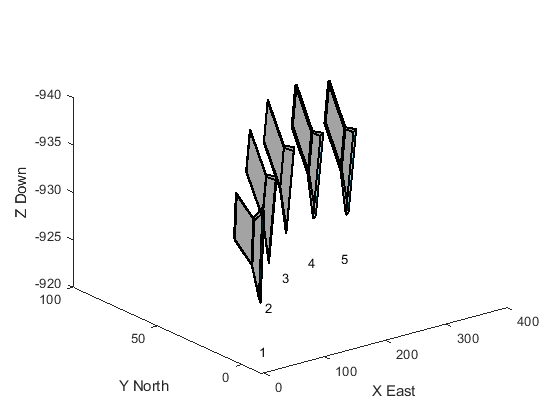

figure;plotCamera(camPoses, 'Size', 5,'Color','k');
xlabel(" X East");
ylabel("Y North");
zlabel("Z Down");
set(gca, 'ZDir','reverse');

## Calculate estimated points before Bundle Adjustment

xyz_est=triangulateMultiview(tracks, camPoses, intrinsics);
D_est=sqrt(xyz_est(:,1).^2+xyz_est(:,2).^2);


## Show estimated points with DEM (before Bundle Adjustment)

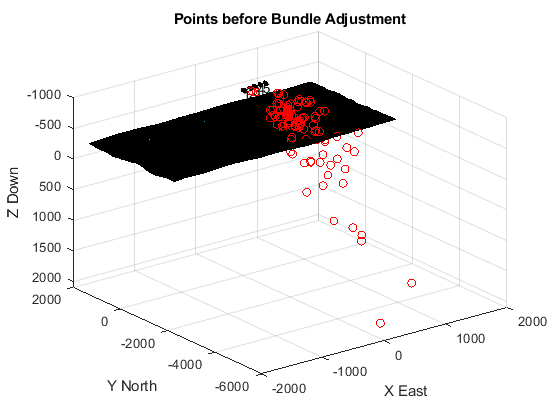

figure;
scatter3(xyz_est(:,1),xyz_est(:,2),xyz_est(:,3),'r');
hold on; 
plotCamera(camPoses, 'Size', 20,'Color','k');
load('DEMs/uavision_DEM_large');
res=30;%m/square
DEM_X=res*size(small_A,1)/-2:res:res*size(small_A,1)/2; DEM_X=DEM_X(1:size(small_A,1));
DEM_Y=res*size(small_A,2)/-2:res:res*size(small_A,2)/2; DEM_Y=DEM_Y(1:size(small_A,2));
hold on;
surf(DEM_X,DEM_Y,-small_A);
set(gca, 'ZDir','reverse');
xlabel(" X East");
ylabel("Y North");
zlabel("Z Down");
title("Points before Bundle Adjustment");

## After Bundle Adjustment

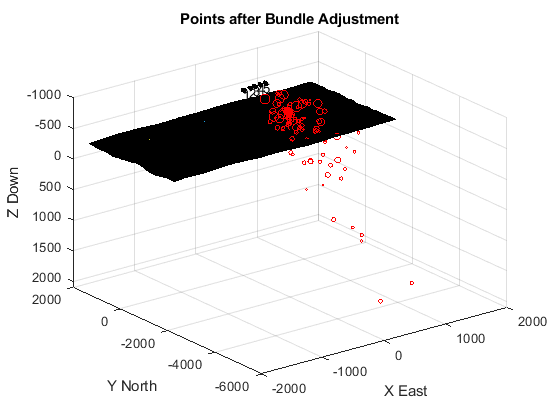

figure;
scatter3(xyzPoints(:,1),xyz_est(:,2),xyzPoints(:,3),reprojectionErrors/2,'r');
hold on; 
plotCamera(camPoses, 'Size', 20,'Color','k');
load('DEMs/uavision_DEM_large');
res=30;%m/square
DEM_X=res*size(small_A,1)/-2:res:res*size(small_A,1)/2; DEM_X=DEM_X(1:size(small_A,1));
DEM_Y=res*size(small_A,2)/-2:res:res*size(small_A,2)/2; DEM_Y=DEM_Y(1:size(small_A,2));
hold on;
surf(DEM_X,DEM_Y,-small_A);
title("Points after Bundle Adjustment");
set(gca, 'ZDir','reverse');
xlabel(" X East");
ylabel("Y North");
zlabel("Z Down");

## Show all final matches

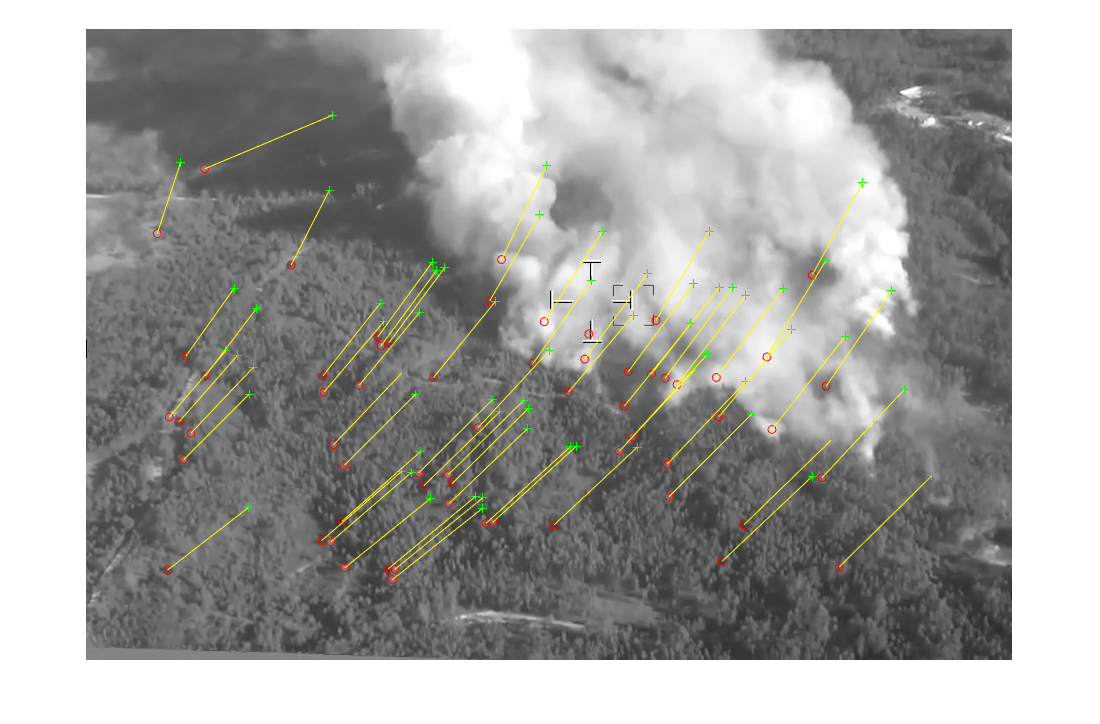

figure; ax = axes;
showMatchedFeatures(images{size(images,2)-1},images{size(images,2)-1},matchedPoints1,matchedPoints2,'Parent',ax);

## Show points above  the camera in the image (before Bundle Adjustment)

bad_mask= xyz_est(:,3)<cam_z(1) ; 
fprintf("Outliers:%d\n",sum(bad_mask));

Outliers:0


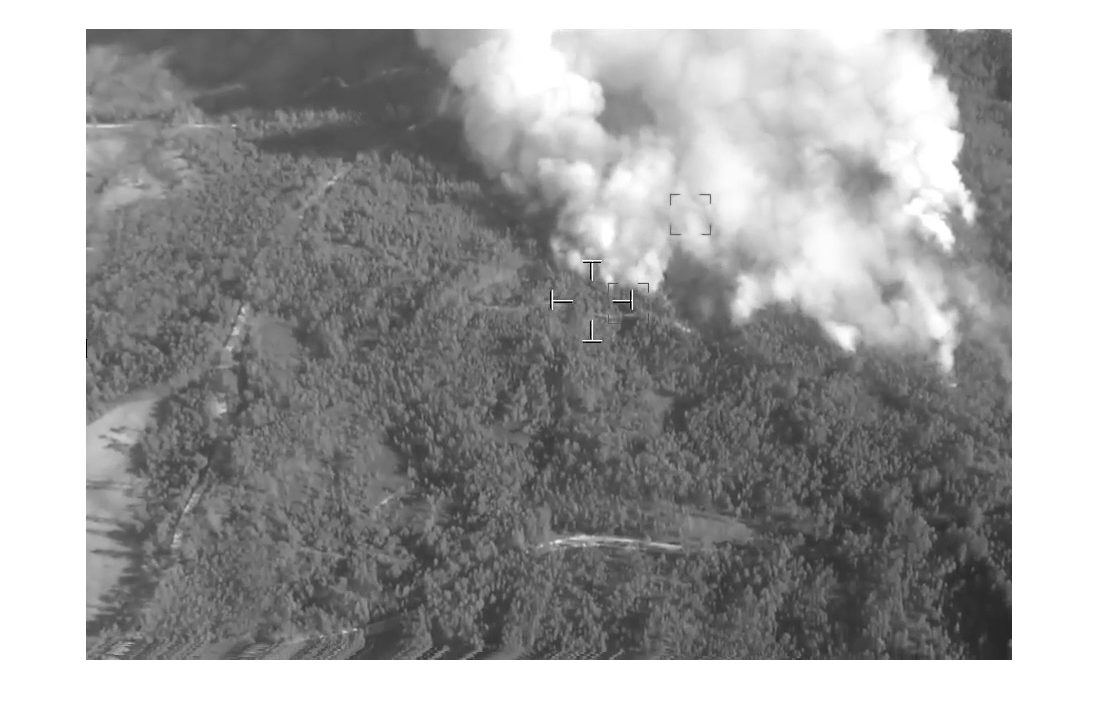

pixels=zeros(size(tracks,2),2);
for i=1:size(tracks,2)
    pixels(i,:)=tracks(i).Points(2,:);
end
bad_pixels=pixels(bad_mask,:);
figure;imshow(I);hold on;
scatter(bad_pixels(:,1),bad_pixels(:,2),reprojectionErrors(bad_mask));

## Show the other points (Before Bundle Adjustment)

figure;imshow(I);hold on;
fprintf("Inliers:%d\n",sum(~bad_mask));

Inliers:112


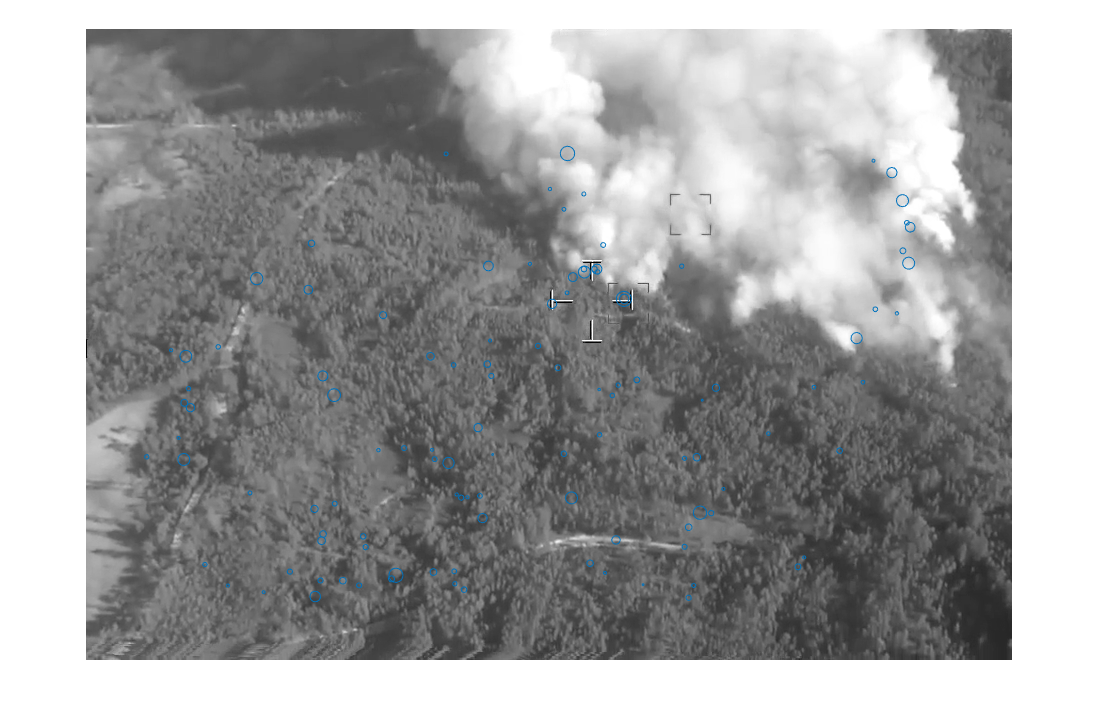

good_pixels=pixels(~bad_mask,:);
scatter(good_pixels(:,1),good_pixels(:,2),reprojectionErrors(~bad_mask));